clear; clc; close all;

% fail laps 
failSubLaps= [3, 0,0,3,0, 5];

trial = 4;

addpath("utils/")
dataPath = sprintf('DataSets/Algo2/lap%d.csv', trial);
[~, timedelta, data] = parseDataSet(dataPath);
dt = mean(timedelta) * 1e-9;  % Convert nanoseconds to seconds

xpos = data(:,22);
ypos = data(:,23);
theta = data(:,24);
linvel = data(:, 15); 
angvel = data(:,18);
results = find_all_laps(xpos, ypos, theta, 800, 0.01, 6);
results.laptimes'

ans = 4×1 cell array
    {[14.7100]}
    {[14.2200]}
    {[16.2900]}
    {[14.4600]}


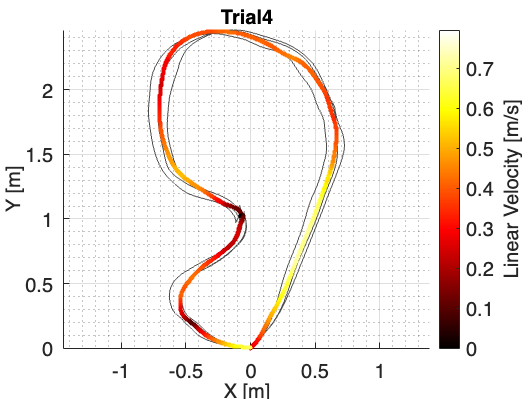

fig = figure;
num_points = 2000;
resampled_laps = zeros(length(results.lap_offsets_aligned), num_points, 3); % x, y, velocity

for k = 1:length(results.lap_offsets_aligned)
    if(k == failSubLaps(trial)) 
        continue
    end
    lap = results.lap_offsets_aligned{k};
    lapRange = results.lap_indices(k,:);
    vel = linvel(lapRange(1):lapRange(end));
    
    lap_len = size(lap,1);
    t_original = linspace(0, 1, lap_len);
    t_uniform = linspace(0, 1, num_points);
    
    x_interp = interp1(t_original, lap(:,1), t_uniform, 'linear', 'extrap');
    y_interp = interp1(t_original, lap(:,2), t_uniform, 'linear', 'extrap');
    vel_interp = interp1(t_original, vel, t_uniform, 'linear', 'extrap');
    
    resampled_laps(k,:,1) = x_interp;
    resampled_laps(k,:,2) = y_interp;
    resampled_laps(k,:,3) = vel_interp;
end

% Compute average lap
avg_traj_x = 1.35*mean(resampled_laps(:,:,1), 1);
avg_traj_y = 1.35*mean(resampled_laps(:,:,2), 1);
avg_vel    = mean(resampled_laps(:,:,3), 1);
hold on; 
for k = 1:length(results.lap_offsets_aligned)
    plot(resampled_laps(k,:,1), resampled_laps(k,:,2), 'Color', [0.3 0.3 0.3]);
end

% Plot average trajectory with velocity as colormap
scatter(avg_traj_x, avg_traj_y, 10, avg_vel, 'filled');
colormap("hot");
xlabel('X [m]', 'FontSize', 16);
ylabel('Y [m]', 'FontSize', 16);
plotTitle = sprintf('Trial%d', trial);
title(plotTitle, 'FontSize', 18);
cb =colorbar();
ylabel(cb, 'Linear Velocity [m/s]');
maxvel = max(avg_vel);
clim([0,1.1*maxvel]);
axis equal; grid on; grid minor; hold off;
fontsize(16, "points");
folderpath = fullfile("..", "Docs", "Y3Report", "Images", "Graphs", filesep);
filepath = fullfile(folderpath, plotTitle + ".pdf");
exportgraphics(fig, filepath)

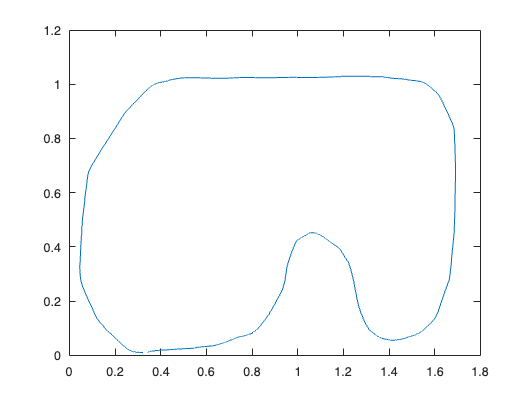

figure; 

T = readtable('DataSets/track.csv', VariableNamingRule="preserve");
scale = 0.001;
plot(T.Var1*scale, T.Var2*scale);

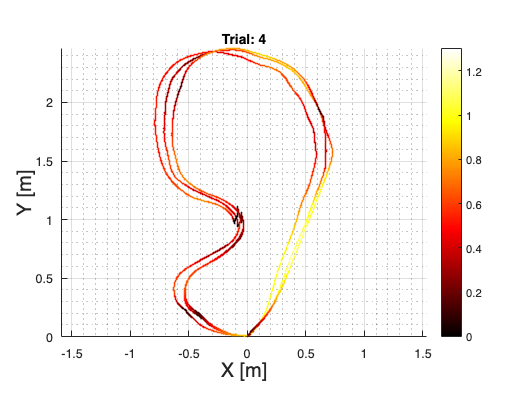

figure; hold on;
colors = lines(size(results.lap_indices,1));
for k = 1:length(results.lap_offsets_aligned)
    lap = results.lap_offsets_aligned{k};
    lapRange = results.lap_indices(k,:);
    if(k == failSubLaps(trial)) 
        continue
    end
    velProfile = linvel(lapRange(1):lapRange(end));
    scatter(lap(:,1), lap(:,2),2, velProfile,"filled");
end
xlabel('X Offset'); ylabel('Y Offset'); 
titelname = sprintf('Trial: %d', trial);
title(titelname);
axis equal; grid on;
xlabel('X [m]', 'FontSize', 16); ylabel('Y [m]','FontSize', 16); 
colormap("hot");
clim([0, 1.3]);

colorbar;  grid on; grid minor; hold off;

function results = find_all_laps(xpos, ypos, theta, min_samples, tolerance, min_displacment)
    % robust_find_all_laps finds loop closures (laps) in drift-heavy odometry data,
    % calculates the offset positions for each lap, and aligns them using the robot's
    % heading (theta) such that all laps can be overlayed.
    %
    %   results = robust_find_all_laps(xpos, ypos, theta, min_samples, tolerance, min_displacment)
    %
    %   INPUTS:
    %       xpos            - Vector of x positions.
    %       ypos            - Vector of y positions.
    %       theta           - Vector of heading angles (in radians) corresponding to xpos/ypos.
    %       min_samples     - Minimum number of samples between lap start and closure 
    %                         (default: 800).
    %       tolerance       - Distance tolerance (in the same units as xpos/ypos) to
    %                         consider a loop closed (default: 0.2).
    %       min_displacment - Minimum cumulative travel distance between a start and its
    %                         candidate closure (default: 3 meters).
    %
    %   OUTPUT:
    %       results - A structure with fields:
    %           lap_indices      : An n-by-2 matrix where each row contains [start_index, closure_index].
    %           lap_offsets      : A cell array where each cell contains a two-column matrix of raw
    %                              offset positions [x_offset, y_offset] for that lap.
    %           lap_offsets_aligned: A cell array where each cell contains a two-column matrix of
    %                              aligned offset positions [x_offset, y_offset] for that lap after
    %                              rotating by the negative starting heading.
    %
    % Example Usage:
    %   results = robust_find_all_laps(xpos, ypos, theta, 800, 0.25, 3);
    %   % Overlay all aligned laps:
    %   figure; hold on;
    %   colors = lines(size(results.lap_indices,1));
    %   for k = 1:length(results.lap_offsets_aligned)
    %       lap = results.lap_offsets_aligned{k};
    %       plot(lap(:,1), lap(:,2), 'Color', colors(k,:), 'LineWidth', 2);
    %   end
    %   xlabel('X Offset (aligned)'); ylabel('Y Offset (aligned)');
    %   title('Overlay of All Aligned Laps');
    %   axis equal; grid on;
    
    % Set default values if necessary
    if nargin < 4 || isempty(min_samples)
        min_samples = 800;
    end
    if nargin < 5 || isempty(tolerance)
        tolerance = 0.2;
    end
    if nargin < 6 || isempty(min_displacment)
        min_displacment = 3; % in meters
    end

    % Precompute cumulative travel distance (along the path)
    ds = sqrt(diff(xpos).^2 + diff(ypos).^2);
    cum_distance = [0; cumsum(ds)];
    
    % Prepare output structure
    results.lap_indices = [];           % Each row: [start_index, closure_index]
    results.lap_offsets = {};           % Cell array of [x_offset, y_offset] relative to lap start
    results.lap_offsets_aligned = {};   % Cell array after aligning (rotating) based on heading
    results.laptimes = {};
    N = length(xpos);
    i = 1;
    
    while i < N - min_samples
        % Define the starting point and heading for the candidate lap.
        start_point = [xpos(i), ypos(i)];
        found = false;
        
        % Look for a candidate closure point j at least min_samples away.
        for j = i + min_samples : N
            % Ensure the robot has traveled a minimum cumulative displacement
            if (cum_distance(j) - cum_distance(i)) < min_displacment
                continue;
            end
            if(cum_distance(j) - cum_distance(i)) > 8
               continue;
            end
            current_point = [xpos(j), ypos(j)];
            dist = norm(current_point - start_point);
            if dist < tolerance
                % Loop closure detected.
                results.lap_indices = [results.lap_indices; i, j]; 
                
                % Compute raw offsets for the lap (translation relative to starting point).
                lap_x = xpos(i:j) - xpos(i);
                lap_y = ypos(i:j) - ypos(i);
                results.lap_offsets{end+1} = [lap_x, lap_y];
                % rotate by -heading so that all laps have zero initial angle.
                heading=theta(j);
                R = [cos(-heading), -sin(-heading); 
                     sin(-heading),  cos(-heading)];
                lap_aligned = (R * [lap_x'; lap_y'])';
                results.lap_offsets_aligned{end+1} = lap_aligned;
                
                % Jump ahead to j to prevent overlapping detections.
                i = j;
                found = true;
                results.laptimes{end+1} = round((results.lap_indices(end,2) - results.lap_indices(end,1)) * 0.01, 2);
                break;
            end
        end
        
        if ~found
            i = i + 1;
        end
    end
end